clc; clear; 
% 
% % I = input('Filename: ');
I = imread('glioma23.jpeg');
I = rgb2gray(I);
% 
% % I = imcrop(I);
% % I = zoom(I);
% [m,n] = size(I)
% for ii=1:m
%     for jj=1:n
%         P = impixel(I,ii,jj) ;
%         if P == 0
%             I(ii,jj)=NaN;
%         end
%     end
% end

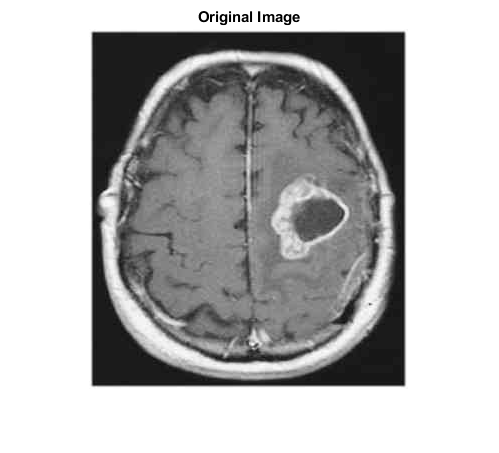

imshow(I)
title('Original Image')

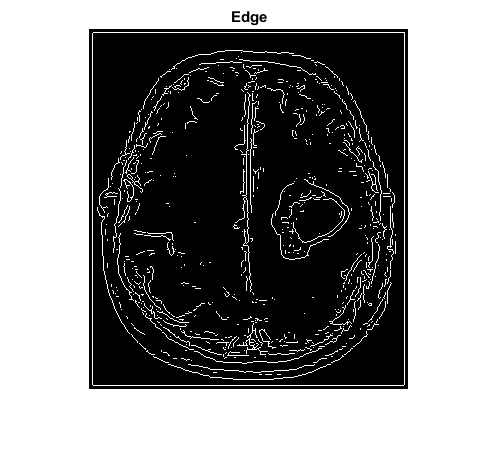


[~, thresh] = edge(I, 'sobel');

fudgeFactor = .4;

Iedge = edge(I, 'sobel', fudgeFactor * thresh);

imshow(Iedge);
title('Edge')

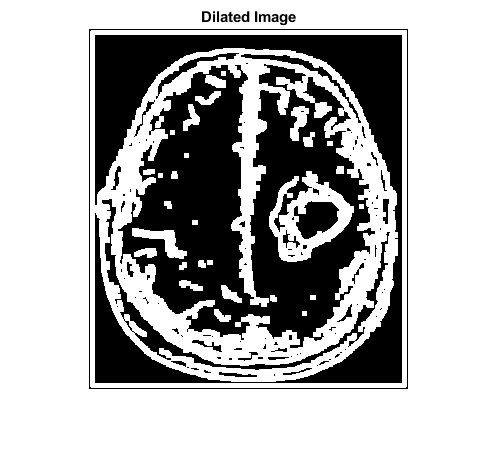


se90 = strel('line',4,90);
se0 = strel('line',4,0);

Idilate = imdilate(Iedge,[se90 se0]);

imshow(Idilate)
title('Dilated Image')

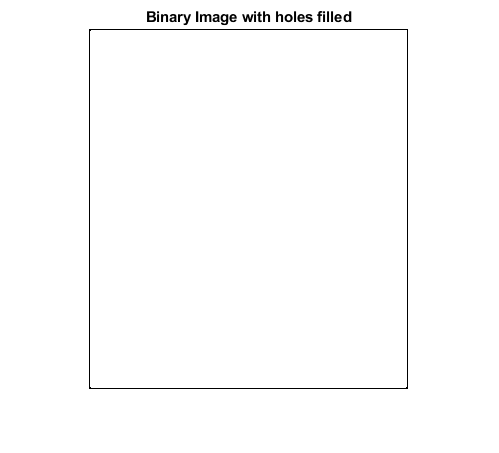


Ifill = imfill(Idilate,'holes');
imshow(Ifill)
title('Binary Image with holes filled')

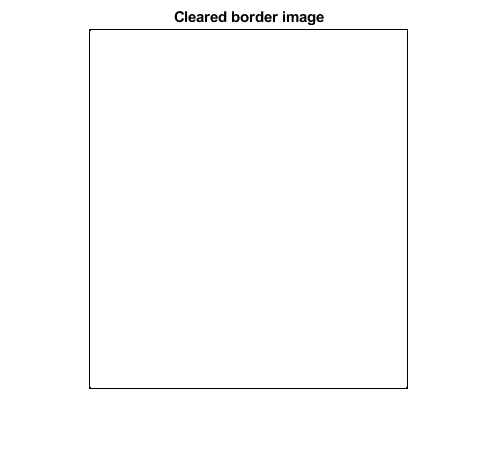



Iclear = imclearborder(Ifill,1);

imshow(Iclear)
title('Cleared border image')

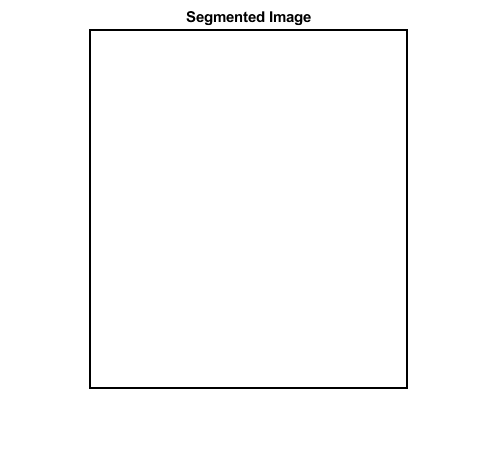


seD = strel('disk',1);

Ifinal = imerode(Iclear,seD);
% Ifinal = imerode(Ifinal,seD);

imshow(Ifinal)
title('Segmented Image')

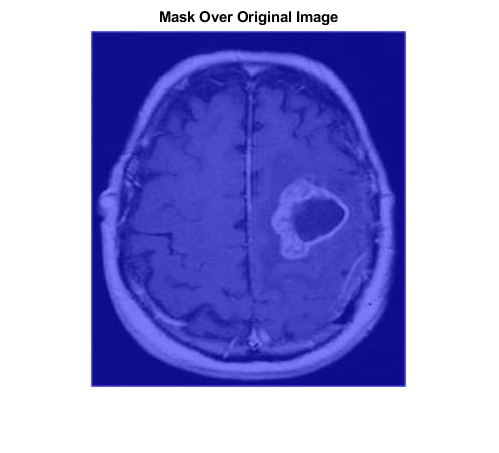


imshow(labeloverlay(I,Ifinal))
title('Mask Over Original Image')